# Rocky Calibration

format longg

step_mag = 300;

measurement_delta_time = 0.02;  % 20 ms

time = 0:measurement_delta_time:measurement_delta_time * (length(left) - 1);

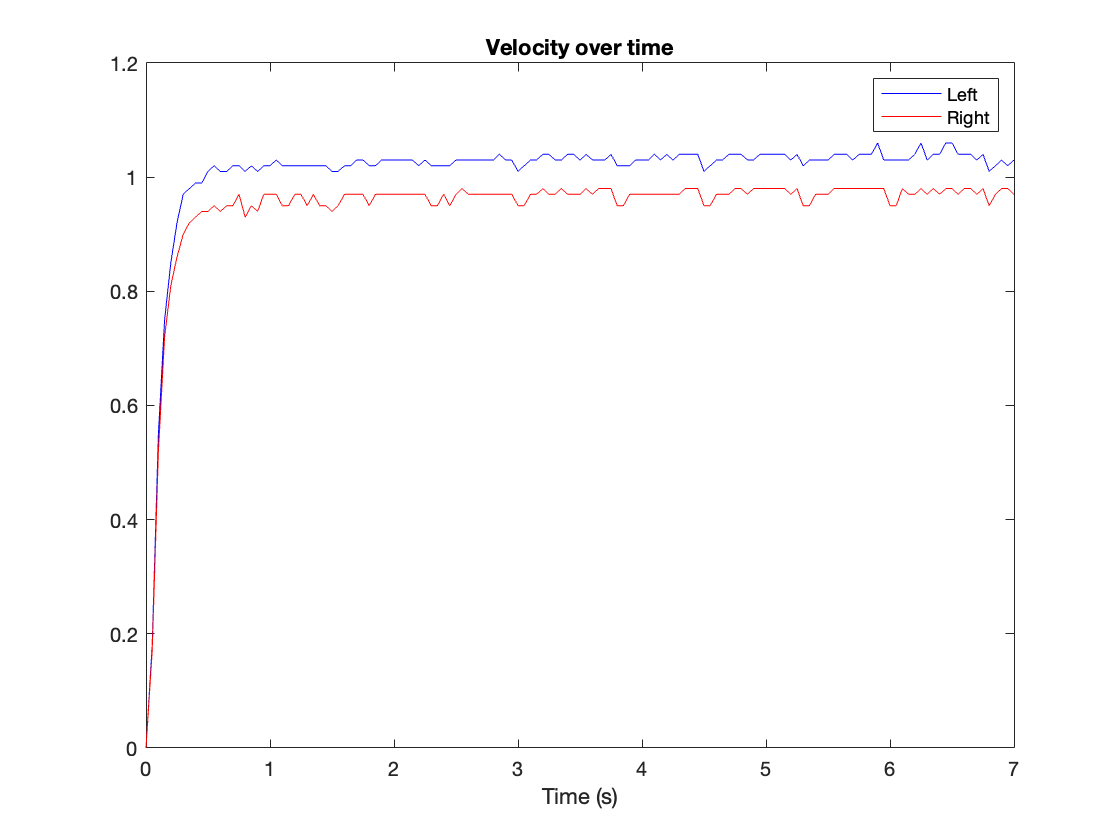

plot(time, left, 'b', time, right, 'r')
legend("Left", "Right")
title("Velocity over time")
xlabel("Time (s)")

left_steady_state = left(time > 1);
left_steady_state_average = mean(left_steady_state)

left_steady_state_average =                      1.031


left_K = left_steady_state_average / step_mag

left_K =        0.00343666666666667


right_steady_state = right(time > 1);
right_steady_state_average = mean(right_steady_state)

right_steady_state_average =          0.969416666666667


right_K = right_steady_state_average / step_mag

right_K =        0.00323138888888889


time_constant_pcnt = 1-exp(-1)

time_constant_pcnt =          0.632120558828558


left_time_constant_target = time_constant_pcnt * left_steady_state_average

left_time_constant_target =          0.651716296152243


left_time_constant = find(left>left_time_constant_target, 1, 'first') * measurement_delta_time

left_time_constant =                       0.08


right_time_constant_target = time_constant_pcnt * right_steady_state_average

right_time_constant_target =          0.612788205071051


right_time_constant = find(right>right_time_constant_target, 1, 'first') * measurement_delta_time

right_time_constant =                       0.08


a = 1/(right_time_constant)

a =                       12.5


b = right_K

b =        0.00323138888888889


Gyro calibration

measured_length = 0.5;  % meter
g = 9.8;

measurement_delta_time = 0.05  % 50 ms

measurement_delta_time =                       0.05


time = 0:measurement_delta_time:measurement_delta_time * (length(gyro) - 1);

plot(time, gyro)
xlabel("seconds")
ylabel("angle")
gyro_interest = gyro; %gyro((time > 10) & (time < 35))
findpeaks(gyro_interest)

[pks, locs] = findpeaks(gyro_interest);
peak_times = time(locs)

peak_times =                       1.15                      2.45                       3.8                       5.1                      6.35                      7.65


freq = (length(peak_times) - 1)/(peak_times(end) - peak_times(1)) * pi * 2

freq =           4.83321946706122


effective_length = (g / freq^2)

effective_length =            0.4195203608711
